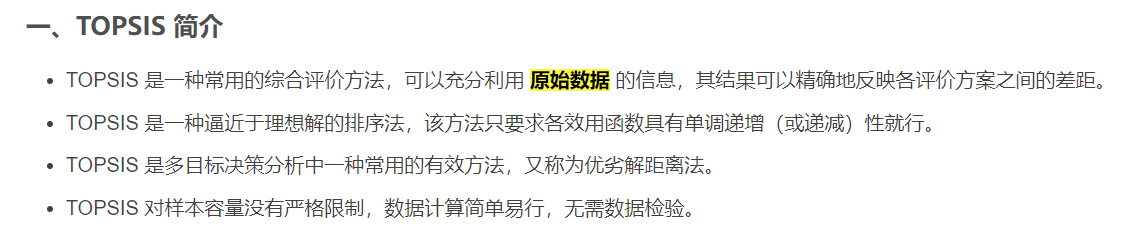

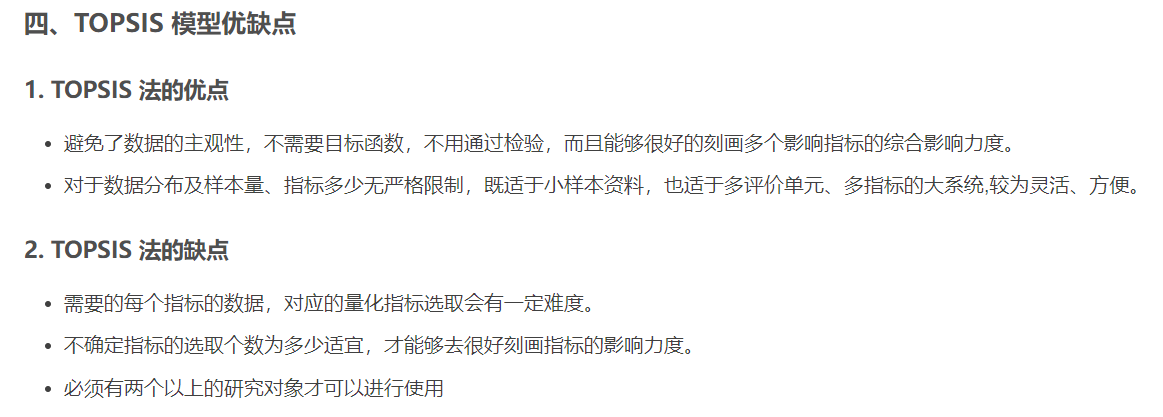

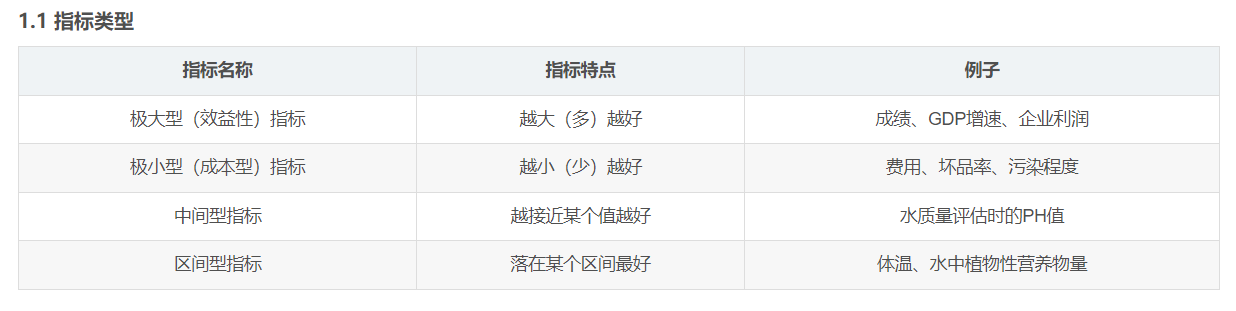

Topsis优化：因为Topsis默认权重相同，所以可以采用层次分析法获得指标的权重进行优化

clc,clear;
load data_water_quality.mat
[n,m] = size(x);
disp(['共有' num2str(n) '个评价对象, ' num2str(m) '个评价指标']) 

共有20个评价对象, 4个评价指标


Judge = input(['这' num2str(m) '个指标是否需要经过正向化处理，需要请输入1 ，不需要输入0：  ']);
if Judge == 1
    Position = input('请输入需要正向化处理的指标所在的列，例如第2、3、6三列需要处理，那么你需要输入[2,3,6]： '); %[1,2,3,4]
    disp('请输入需要处理的这些列的指标类型（1：极小型， 2：中间型， 3：区间型） ')
    Type = input('例如：第2列是极小型，第3列是区间型，第6列是中间型，就输入[1,3,2]：  '); %[1,1,1,1]
    % 注意，Position和Type是两个同维度的行向量
    for i = 1 : size(Position,2)  %这里需要对这些列分别处理，因此我们需要知道一共要处理的次数，即循环的次数
        x(:,Position(i)) = Positivization(x(:,Position(i)),Type(i),Position(i));
    % Positivization是我们自己定义的函数，其作用是进行正向化，其一共接收三个参数
    % 第一个参数是要正向化处理的那一列向量 X(:,Position(i))   回顾上一讲的知识，X(:,n)表示取第n列的全部元素
    % 第二个参数是对应的这一列的指标类型（1：极小型， 2：中间型， 3：区间型）
    % 第三个参数是告诉函数我们正在处理的是原始矩阵中的哪一列
    % 该函数有一个返回值，它返回正向化之后的指标，我们可以将其直接赋值给我们原始要处理的那一列向量
    end
    disp('正向化后的矩阵 X =  ')
    disp(x)
end

请输入需要处理的这些列的指标类型（1：极小型， 2：中间型， 3：区间型） 


第1列是区间型
第1列区间型正向化处理完成
~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~
第2列是极小型，正在正向化
第2列极小型正向化处理完成
~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~
第3列是区间型
第3列区间型正向化处理完成
~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~
第4列是区间型
第4列区间型正向化处理完成
~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~


正向化后的矩阵 X =  


    0.4675    1.8200    0.0566    0.6421
    0.1470    0.5500    0.6604    0.8214
    0.0229    2.1000    0.1509    0.7412
    0.9398    1.3600    0.1509    0.1681
    0.7614    1.9100    0.0755    0.2617
    0.1904    1.6400    0.3019    0.2273
    0.8289    1.6200    0.3019    0.8361
         0    1.6000    0.5094         0
    0.5590    0.7900    0.9245    0.4289
    0.6482    1.1400    0.6981    0.7870
    0.8578    0.8800    0.8491    0.8194
    0.4325    1.1300    0.6981    0.2051
    0.8012    0.1700    0.5849    0.5610
    0.1446    2.8600    0.1321    0.1721
    0.1482    2.0100    0.5849    0.4468
    0.8337    2.2700    0.0377    0.5185
    0.6675    0.8300    0.5472    0.0690
    0.9012         0    0.2830    0.6395
    0.3289    1.1400         0    0.9293
    0.7988    2.1500    0.8679    0.1034



Z = x ./ repmat(sum(x.*x) .^ 0.5, n, 1);
disp('标准化矩阵 Z = ')

标准化矩阵 Z = 


disp(Z)

    0.1711    0.2590    0.0245    0.2600
    0.0538    0.0783    0.2863    0.3325
    0.0084    0.2988    0.0655    0.3001
    0.3439    0.1935    0.0655    0.0681
    0.2787    0.2718    0.0327    0.1059
    0.0697    0.2334    0.1309    0.0920
    0.3034    0.2305    0.1309    0.3385
         0    0.2277    0.2209         0
    0.2046    0.1124    0.4009    0.1736
    0.2372    0.1622    0.3027    0.3186
    0.3139    0.1252    0.3682    0.3317
    0.1583    0.1608    0.3027    0.0830
    0.2932    0.0242    0.2536    0.2271
    0.0529    0.4070    0.0573    0.0697
    0.0542    0.2860    0.2536    0.1809
    0.3051    0.3230    0.0164    0.2099
    0.2443    0.1181    0.2373    0.0279
    0.3298         0    0.1227    0.2589
    0.1204    0.1622         0    0.3762
    0.2923    0.3059    0.3763    0.0418



D_P = sum([(Z - repmat(max(Z),n,1)) .^ 2 ],2) .^ 0.5;   % D+ 与最大值的距离向量
D_N = sum([(Z - repmat(min(Z),n,1)) .^ 2 ],2) .^ 0.5;   % D- 与最小值的距离向量
S = D_N ./ (D_P+D_N);    % 未归一化的得分
disp('最后的得分为：')

最后的得分为：


stand_S = S / sum(S)%归一化后的得分

stand_S =     0.0473
    0.0498
    0.0467
    0.0448
    0.0458
    0.0365
    0.0618
    0.0359
    0.0565
    0.0646


%[sorted_S,index] = sort(stand_S ,'descend')

function [posit_x] = Min2Max(x)
    posit_x = max(x) - x;
     %posit_x = 1 ./ x;    %如果x全部都大于0，也可以这样正向化
end
function [posit_x] = Mid2Max(x,best)
    M = max(abs(x-best));
    posit_x = 1 - abs(x-best) / M;
end
function [posit_x] = Inter2Max(x,a,b)
    r_x = size(x,1);  % row of x 
    M = max([a-min(x),max(x)-b]);
    posit_x = zeros(r_x,1);   %zeros函数用法: zeros(3)  zeros(3,1)  ones(3)
    % 初始化posit_x全为0  初始化的目的是节省处理时间
    for i = 1: r_x
        if x(i) < a
           posit_x(i) = 1-(a-x(i))/M;
        elseif x(i) > b
           posit_x(i) = 1-(x(i)-b)/M;
        else
           posit_x(i) = 1;
        end
    end
end
% function [输出变量] = 函数名称(输入变量）  
% 函数的中间部分都是函数体
% 函数的最后要用end结尾
% 输出变量和输入变量可以有多个，用逗号隔开
% function [a,b,c]=test(d,e,f)
%     a=d+e;
%     b=e+f;
%     c=f+d;
% end
% 自定义的函数要单独放在一个m文件中，不可以直接放在主函数里面（和其他大多数语言不同）
 
function [posit_x] = Positivization(x,type,i)
% 输入变量有三个：
% x：需要正向化处理的指标对应的原始列向量
% type： 指标的类型（1：极小型， 2：中间型， 3：区间型）
% i: 正在处理的是原始矩阵中的哪一列
% 输出变量posit_x表示：正向化后的列向量
    if type == 1  %极小型
        disp(['第' num2str(i) '列是极小型，正在正向化'] )
        posit_x = Min2Max(x);  %调用Min2Max函数来正向化
        disp(['第' num2str(i) '列极小型正向化处理完成'] )
        disp('~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~')
    elseif type == 2  %中间型
        disp(['第' num2str(i) '列是中间型'] )
        best = input('请输入最佳的那一个值： ');
        posit_x = Mid2Max(x,best);
        disp(['第' num2str(i) '列中间型正向化处理完成'] )
        disp('~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~')
    elseif type == 3  %区间型
        disp(['第' num2str(i) '列是区间型'] )
        a = input('请输入区间的下界： ');
        b = input('请输入区间的上界： '); 
        posit_x = Inter2Max(x,a,b);
        disp(['第' num2str(i) '列区间型正向化处理完成'] )
        disp('~~~~~~~~~~~~~~~~~~~~分界线~~~~~~~~~~~~~~~~~~~~')
    else
        disp('没有这种类型的指标，请检查Type向量中是否有除了1、2、3之外的其他值')
    end
end 
